1

eps = 1e-12;
newton(@f1,@f1d,0,eps)

ans = -0.7577

newton(@atan,@f2d,2,eps)

ans = NaN

newton(@atan,@f2d,1,eps)

ans = 0

2

% initialize question
global lambda;
lambda = 48;
c1 = 1e6;
c2 = 1e3;

r = 0.1;
b = 0.3;
h = 0.3;
T0 = zeros(18,1)+300;
T1 = 600;
T2 = 300;

nodes = gen_nodes(r,b,h);
elements = [1 2 6 5
    2 3 7 6
    3 4 8 7
    5 6 10 9
    6 7 11 10
    7 12 14 11
    7 8 13 12
    9 10 16 15
    10 11 17 16
    11 14 18 17
    ];
dbc = [1 T1
    2 T1
    3 T1
    4 T1
    12 T2
    13 T2
    14 T2
    18 T2
    ];
T0(dbc(:,1)) = dbc(:,2);

max_k = 1000;
eps = 1e-8;

sol = solve_question(nodes,elements,dbc,c1,c2,T0,max_k,eps);
% display solution
display(sol(15:18));

  479.5700
  434.1886
  373.1416
  300.0000



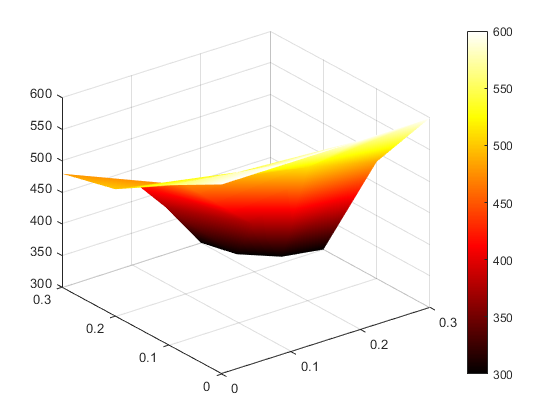

figure;
quadplot(nodes,elements,sol);
shading interp;
colormap hot;
colorbar;


sol_new = sol;
T2_new = T2;
while ~all(sol_new(nodes(:,2)==h)<450)
    T2_new = T2_new - 10;
    dbc_new = [1 T1
    2 T1
    3 T1
    4 T1
    12 T2_new
    13 T2_new
    14 T2_new
    18 T2_new
    ];
    T0_new = zeros(18,1)+300;
    T0_new(dbc_new(:,1)) = dbc_new(:,2);
    sol_new = solve_question(nodes,elements,dbc_new,c1,c2,T0_new,max_k,eps);
end

display(sol_new(15:18));

  443.8316
  394.4872
  328.5025
  250.0000



display(T2_new);

T2_new = 250

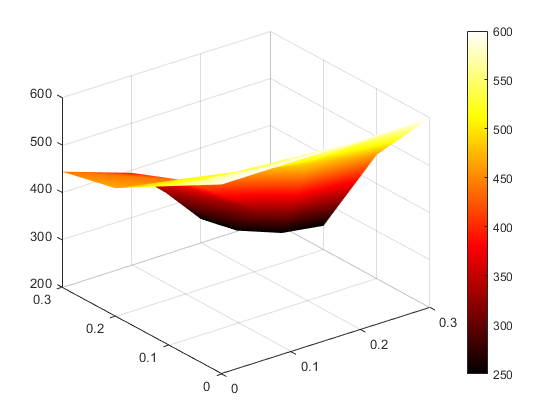

quadplot(nodes,elements,sol_new);
shading interp;
colormap hot;
colorbar;

function x = newton(f,fd,x0,eps)
    x = x0;
    err = abs(f(x0));
    while err>eps
        x = x - f(x)/fd(x);
        err = abs(f(x));
    end
end

function y = f1(x)
    y = x^3 + 3^x;
end

function y = f1d(x)
    y = 3^x*log(3) + 3*x^2;
end

function y = f2d(x)
    y = 1/(x^2 + 1);
end

function nodes = gen_nodes(r,b,h)
    nodes = zeros(18,2);
    [x, y] = meshgrid(linspace(0,b,4),linspace(0,h,4));
    nodes([1:11,15:16],:) = [y([1:11,13:14])',x([1:11,13:14])'];
    nodes(12,:)=[b-r*sin(pi/6),b-r*cos(pi/6)];
    nodes(13,:)=[b,h-r];
    nodes(14,:)=[b-r*cos(pi/6),b-r*sin(pi/6)];
    nodes(17,:)=[b/2,h];
    nodes(18,:)=[b-r,h];
end

function y = F(elenodes,gpx,gpw,c1,c2,T)
    [A,~] = evaluate_stat(elenodes,gpx,gpw);
    A = A * T;
    M = zeros(4,1);
    for i=1:4
        for k=1:numel(gpw)
            xi = gpx(k,1);
            eta = gpx(k,2);
            w = gpw(k);
            [~,detJ,~] = getJacobian(elenodes, xi, eta);
            N = linquadref(xi,eta);
            p2 = exp(-c2/(T'*N));
            M(i) = M(i) + N(i) * detJ * w * c1 * p2;
        end
    end
    y = A-M;
end

function J = FJacobi(elenodes,gpx,gpw,c1,c2,T)
    [A,~] = evaluate_stat(elenodes,gpx,gpw);
    M = zeros(4);
    for i=1:4
        for j=1:4
            for k=1:numel(gpw)
                xi = gpx(k,1);
                eta = gpx(k,2);
                w = gpw(k);
                [~,detJ,~] = getJacobian(elenodes, xi, eta);
                N = linquadref(xi,eta);
                p1 = (c1*c2)/(T'*N)^2;
                p2 = exp(-c2/(T'*N));
                M(i,j) = M(i,j) + N(i) * N(j)' * detJ * w * p1 * p2;
            end
        end
    end
    J = A-M;
end

function [elemat,elevec] = Evaluieren(elenodes,gpx,gpw,c1,c2,T)
    elemat = FJacobi(elenodes,gpx,gpw,c1,c2,T);
    elevec = -F(elenodes,gpx,gpw,c1,c2,T);
end

function [sysmat,rhs] = assignDBC_nlin(sysmat,rhs, dbc)
    eyes = eye(size(sysmat));
    for i=1:size(dbc,1)
        sysmat(dbc(i,1),:) = eyes(dbc(i,1),:);
        rhs(dbc(i,1)) = 0;
    end
end

function sol = solve_question(nodes,elements,dbc,c1,c2,T0,max_k,eps)
    % solve question
    n = 3;
    gpx = gx2dref(n);
    gpw = gw2dref(n);
    sol = T0;
    for k=1:max_k
        sysmat = zeros(size(nodes,1));
        rhs = zeros(size(nodes,1),1);
        for i=1:size(elements,1)
            ele = elements(i,:);
            elenodes = nodes(ele,:);
            elesol = sol(ele);
            [elemat,elevec] = Evaluieren(elenodes,gpx,gpw,c1,c2,elesol);
            [sysmat,rhs] = assemble(elemat,elevec,sysmat,rhs,ele);
        end
        [sysmat,rhs] = assignDBC_nlin(sysmat,rhs,dbc);
        % delta_T = solveCG(sysmat,rhs,zeros(size(rhs)), 1e-7, 1000);
        delta_T = sysmat\rhs;
        sol = sol + delta_T;
        if norm(delta_T)<eps
            break
        end
    end
end
